load('pilot_master_long.mat')

master = sortrows(master,"Pair","ascend");

%% ALL SUBJECTS %%%
% clearvars -except subtable
% master = sortrows(subtable,"Pair","ascend");

cuehl = master.highcue_indx;
cuemean = master.cue_observed_mean;
pair = master.Pair;
rating = master.img_rate;
stimmean = master.Valence_mean;

wh_high = cuehl > 0;
wh_low = cuehl < 0;

hi_table_all = master(wh_high, :);
lo_table_all = master(wh_low, :);

numArrays = 4;
groups = cell(numArrays,1);
for n = 1:numArrays
    hi_table = hi_table_all(hi_table_all.group == n, :);
    lo_table = lo_table_all(lo_table_all.group == n, :);

pair_table = table;
pair_table.pair_number = hi_table.Pair;
pair_table.hi_cue = hi_table.img_rate;
pair_table.lo_cue = lo_table.img_rate;
pair_table.rating_mean = (hi_table.img_rate + lo_table.img_rate)/2;
pair_table.cue_mean = (hi_table.cue_observed_mean + lo_table.cue_observed_mean)/2;
pair_table.cue_sd = (hi_table.cue_observed_std + lo_table.cue_observed_std)/2;
pair_table.stim_mean = (hi_table.Valence_mean + lo_table.Valence_mean)/2;
pair_table.stim_sd = (hi_table.Valence_SD + lo_table.Valence_SD)/2;
pair_table.rating_diff = hi_table.img_rate - lo_table. img_rate;
pair_table.stim_diff = (hi_table.Valence_mean - lo_table.Valence_mean);
pair_table.norm_hi = pair_table.hi_cue - pair_table.rating_mean;
pair_table.norm_lo = pair_table.lo_cue - pair_table.rating_mean;
d = pair_table.rating_diff;

% Two-tailed
[hyp, pval, ci, stat] = ttest(pair_table.hi_cue, pair_table.lo_cue, 'Tail', 'right', 'Alpha', 0.99);
fprintf('High vs. low cue effect: M = %3.2f, SE = %3.2f, t(%3.0f) = %3.2f, p = %3.6f\n', mean(d), ste(d), stat.df(1), stat.tstat(1), pval(1));
groups{n}.hyp = hyp;
groups{n}.pval = pval;
groups{n}.ci = ci;
groups{n}.stat = stat;
groups{n}.pair_table = pair_table;
groups{n}.d = d;
groups{n}.SE = ste(d);
groups{n}.mean = mean(pair_table.rating_diff);
end

High vs. low cue effect: M = 4.55, SE = 0.56, t(1023) = 8.17, p = 0.000000
High vs. low cue effect: M = 4.26, SE = 0.54, t(959) = 7.83, p = 0.000000
High vs. low cue effect: M = 3.72, SE = 0.58, t(991) = 6.46, p = 0.000000
High vs. low cue effect: M = 4.21, SE = 0.60, t(959) = 7.02, p = 0.000000




%%
figure; hold on;
for i = 1:4
    y(i) = groups{i}.mean;
    SEs(i) = groups{i}.SE;
    errlow(i) = groups{i}.mean - groups{i}.SE;
    errhigh(i) = groups{i}.mean + groups{i}.SE;
end
b = bar([1 2 3 4], y )

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [0 0.4470 0.7410]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2 3 4]
        YData: [4.5469 4.2604 3.7167 4.2052]

  Show all properties


b.FaceColor = 'flat'

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: 'flat'
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2 3 4]
        YData: [4.5469 4.2604 3.7167 4.2052]

  Show all properties


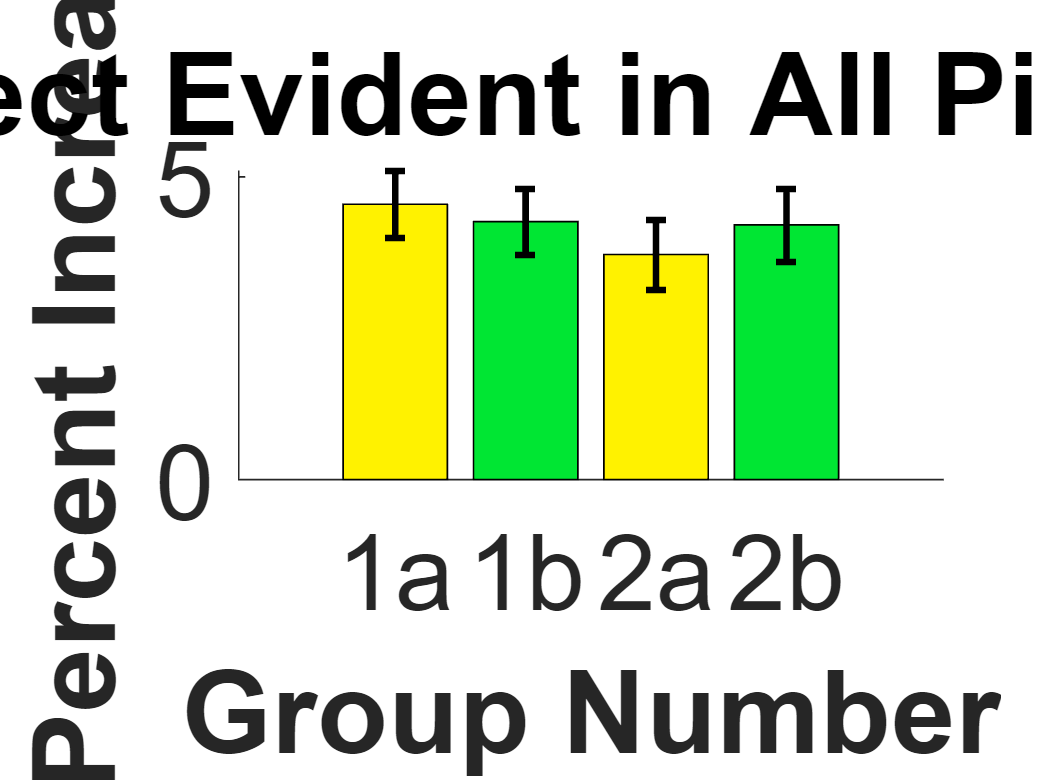

b.CData(1, :) = [1 .95 0];
b.CData(3, :) = [1 .95 0];

b.CData(2, :) = [0 .9 .2];
b.CData(4, :) = [0 .9 .2];
er = errorbar(1:4,y,SEs);

er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
er.LineWidth = 2;

set(gca, 'FontSize', 32)
scn_export_papersetup(400);
ylabel('Percent Increase', 'FontWeight', 'bold');
xlabel('Group Number', 'FontWeight', 'bold');
title('Cue Effect Evident in All Pilot Groups')
set(gca, 'XTick', 1:4, 'XTickLabel', ['1a'; '1b'; '2a'; '2b']);

drawnow()